## Optimisation des paramètres pour la séquence clinique :

Problématique: Trouver le meilleur compromis Signal / Temps d'acquisition tout en gardant des paramètres permettant d'avoir un bon CNR.

Nous cherchons donc à maximiser le ratio Signal / Temps d'acquisition:

%S3D = B0 * delta_x * delta_y * SliceThick * sqrt(Reso_x*Reso_y*Nb_slice*Nex)/ sqrt(BW)
%S3D_Sense = S3D/sqrt(SENSE_S*SENSE_P)

%Tmps_acqui_ms = (TR*Nex*Reso_y*Nb_slice)/(SENSE_P*SENSE_S)
%Tmps_acqui_min = Tmps_acqui_ms / 60000

SENSE =      1     2     3     4


R_SENSE =     1.0000    1.4142    1.7321    2.0000


### *1) **Simplifier l'équation :*

***Hypothèse simplificatrice 1 :*** B0, FOV(x,y,z), Matrice(x,y) et épaisseur de coupe = Constantes  -> Cela nous permettra de comparer des séquences à champ magnétique donné et ayant des voxels de même volume.

Conséquences: B0 * delta_x * delta_y * SliceThick = Ca; Reso_x*Reso_y*Nb_slice = Cb; Reso_y*Nb_slice = Cc -> Ca, Cb, Cc = Constantes

- Signal = Ca * sqrt(Cb) * sqrt(Nex) / sqrt(BW * SENSE_S * SENSE_P)

- Temps_acqui_min = (TR * Nex *Cc) / (SENSE_P*SENSE_S) * (1/60000)

***Hypothèse simplicatrice 2 : ***Nombre d'échos = Constante; et SENSE_S * SENSE_P = SENSE (Facteur SENSE "total")

- BW = Nb_Echos / ((Nb_echoes - 1) * (inter_echoes* 10^-3)) -> inter_echoes en ms

- Te_total = (Nb_echoes - 1) * (inter_echoes* 10^-3 )

- Signal= **Ca * sqrt(Cb)** * **sqrt(Nex)** / sqrt( (Nb_echoes/Te_total) * SENSE)

- Temps_acqui_min = ((TR * Nex *Cc) / **(SENSE))** * **(1/60000)**

Ce qui donne donc : 

S_T_Ratio = Signal / Temps_acqui_min = ((60000* Ca * sqrt(Cb)) / Cc ) * ( (SENSE*sqrt(Nex)) / ( sqrt (Nb_echoes/Te_total) * sqrt(SENSE) * TR * Nex)

S_T_Ratio = K * (SENSE*sqrt(Nex)) / ( sqrt (Nb_echoes/Te_total) * sqrt(SENSE) * TR * Nex)

*Où K = Constante*

**Pour maximiser **le ratio Signal / Temps d'acquisition, on cherchera donc à maximiser : (SENSE*sqrt(Nex)) / ( sqrt ((Nb_echoes/Te_total) * SENSE))

### *2) **Développer l'équation :*

S_T_Ratio = K * (SENSE / sqrt(SENSE) ) * ( sqrt(Nex) / Nex ) * ( 1 / sqrt(Nb_echoes/Te_total) ) * (1/TR)

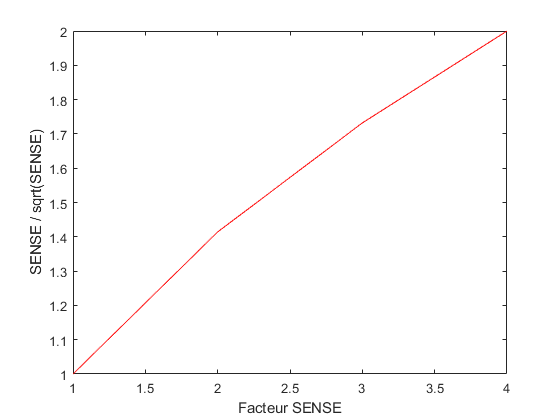

SENSE = [1:4] % Facteurs SENSE envisageables
R_SENSE = SENSE ./ sqrt(SENSE)
plot(SENSE, R_SENSE,"r")

xlabel("Facteur SENSE")
ylabel("SENSE / sqrt(SENSE)")

NEX =      1     2     3     4


NEX = [1:4] % Nex enviseageables

R_nex =     1.0000    0.7071    0.5774    0.5000


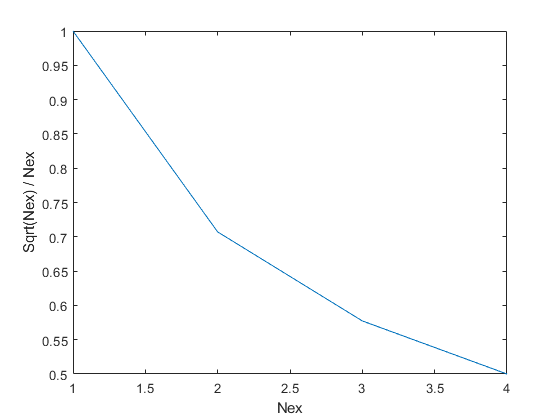

R_nex = sqrt(NEX)./NEX
plot(NEX, R_nex)
xlabel("Nex")

ylabel("Sqrt(Nex) / Nex")

Nb_echoes = 4

Nb_echoes = 4

inter_echoes = [6:9]'

inter_echoes =      6
     7
     8
     9


Te_tot = (Nb_echoes-1)*(inter_echoes)

Te_tot =     18
    21
    24
    27


%Te_tot = [18:3:27]' % Te_total ensigeables = Durée entre Te1 et dernier écho 
R_tetot = 1 ./ (sqrt(4 ./ Te_tot ))

R_tetot =     2.1213
    2.2913
    2.4495
    2.5981


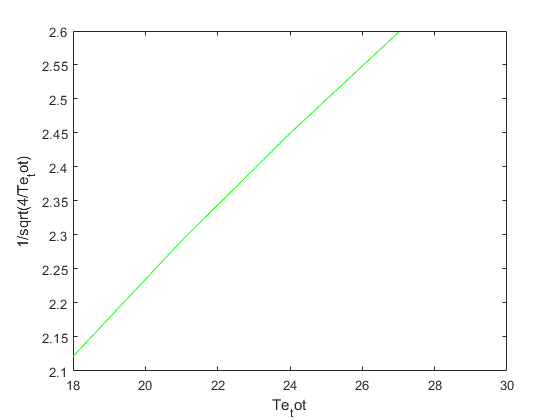

plot(Te_tot, R_tetot, "g")
xlim([18 30])
xlabel("Te_tot")
ylabel("1/sqrt(4/Te tot)")

TR = [30:3:45] % TR enviseageables en ms
R_TR = 1 ./ TR

TR =     30    33    36    39    42    45


plot(TR, R_TR, "--")

R_TR =     0.0333    0.0303    0.0278    0.0256    0.0238    0.0222


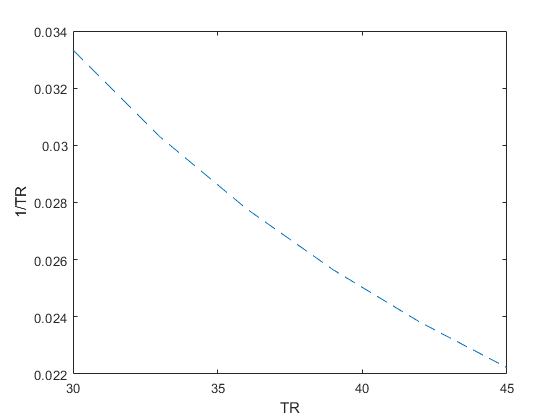

xlabel("TR")
ylabel("1/TR")

### Calcul des ratios signal / temps en fonction des différents paramètres :

***Lecture des matrice et paramètres testés : ***

Paramètre testé (indice du paramètre dans son vecteur)

- TE_tot(numéro ligne) 

- Facteur SENSE(numéro_colonne) 

- Nex(numero_nex) 

- TR(i)

%Boucle Nex = 1
for i = [1:length(R_TR)]
s_t_nex1 = R_tetot .* R_SENSE .* R_nex(1)*R_TR(i)
max_nex1 = max(s_t_nex1)
end

s_t_nex1 =     0.0707    0.1000    0.1225    0.1414
    0.0764    0.1080    0.1323    0.1528
    0.0816    0.1155    0.1414    0.1633
    0.0866    0.1225    0.1500    0.1732


max_nex1 =     0.0866    0.1225    0.1500    0.1732


s_t_nex1 =     0.0643    0.0909    0.1113    0.1286
    0.0694    0.0982    0.1203    0.1389
    0.0742    0.1050    0.1286    0.1485
    0.0787    0.1113    0.1364    0.1575


max_nex1 =     0.0787    0.1113    0.1364    0.1575


s_t_nex1 =     0.0589    0.0833    0.1021    0.1179
    0.0636    0.0900    0.1102    0.1273
    0.0680    0.0962    0.1179    0.1361
    0.0722    0.1021    0.1250    0.1443


max_nex1 =     0.0722    0.1021    0.1250    0.1443


s_t_nex1 =     0.0544    0.0769    0.0942    0.1088
    0.0588    0.0831    0.1018    0.1175
    0.0628    0.0888    0.1088    0.1256
    0.0666    0.0942    0.1154    0.1332


max_nex1 =     0.0666    0.0942    0.1154    0.1332


s_t_nex1 =     0.0505    0.0714    0.0875    0.1010
    0.0546    0.0772    0.0945    0.1091
    0.0583    0.0825    0.1010    0.1166
    0.0619    0.0875    0.1071    0.1237


max_nex1 =     0.0619    0.0875    0.1071    0.1237


s_t_nex1 =     0.0471    0.0667    0.0816    0.0943
    0.0509    0.0720    0.0882    0.1018
    0.0544    0.0770    0.0943    0.1089
    0.0577    0.0816    0.1000    0.1155


max_nex1 =     0.0577    0.0816    0.1000    0.1155




%Boucle Nex=2
for i = [1:length(R_TR)]
s_t_nex2 = R_tetot .* R_SENSE .* R_nex(2)*R_TR(i)
max_nex2 = max(s_t_nex2)
end

s_t_nex2 =     0.0500    0.0707    0.0866    0.1000
    0.0540    0.0764    0.0935    0.1080
    0.0577    0.0816    0.1000    0.1155
    0.0612    0.0866    0.1061    0.1225


max_nex2 =     0.0612    0.0866    0.1061    0.1225


s_t_nex2 =     0.0455    0.0643    0.0787    0.0909
    0.0491    0.0694    0.0850    0.0982
    0.0525    0.0742    0.0909    0.1050
    0.0557    0.0787    0.0964    0.1113


max_nex2 =     0.0557    0.0787    0.0964    0.1113


s_t_nex2 =     0.0417    0.0589    0.0722    0.0833
    0.0450    0.0636    0.0780    0.0900
    0.0481    0.0680    0.0833    0.0962
    0.0510    0.0722    0.0884    0.1021


max_nex2 =     0.0510    0.0722    0.0884    0.1021


s_t_nex2 =     0.0385    0.0544    0.0666    0.0769
    0.0415    0.0588    0.0720    0.0831
    0.0444    0.0628    0.0769    0.0888
    0.0471    0.0666    0.0816    0.0942


max_nex2 =     0.0471    0.0666    0.0816    0.0942


s_t_nex2 =     0.0357    0.0505    0.0619    0.0714
    0.0386    0.0546    0.0668    0.0772
    0.0412    0.0583    0.0714    0.0825
    0.0437    0.0619    0.0758    0.0875


max_nex2 =     0.0437    0.0619    0.0758    0.0875


s_t_nex2 =     0.0333    0.0471    0.0577    0.0667
    0.0360    0.0509    0.0624    0.0720
    0.0385    0.0544    0.0667    0.0770
    0.0408    0.0577    0.0707    0.0816


max_nex2 =     0.0408    0.0577    0.0707    0.0816




%Boucle Nex=3
for i = [1:length(R_TR)]
s_t_nex3 = R_tetot .* R_SENSE .* R_nex(3)*R_TR(i)
max_nex3 = max(s_t_nex3)
end

s_t_nex3 =     0.0408    0.0577    0.0707    0.0816
    0.0441    0.0624    0.0764    0.0882
    0.0471    0.0667    0.0816    0.0943
    0.0500    0.0707    0.0866    0.1000


max_nex3 =     0.0500    0.0707    0.0866    0.1000


s_t_nex3 =     0.0371    0.0525    0.0643    0.0742
    0.0401    0.0567    0.0694    0.0802
    0.0429    0.0606    0.0742    0.0857
    0.0455    0.0643    0.0787    0.0909


max_nex3 =     0.0455    0.0643    0.0787    0.0909


s_t_nex3 =     0.0340    0.0481    0.0589    0.0680
    0.0367    0.0520    0.0636    0.0735
    0.0393    0.0556    0.0680    0.0786
    0.0417    0.0589    0.0722    0.0833


max_nex3 =     0.0417    0.0589    0.0722    0.0833


s_t_nex3 =     0.0314    0.0444    0.0544    0.0628
    0.0339    0.0480    0.0588    0.0678
    0.0363    0.0513    0.0628    0.0725
    0.0385    0.0544    0.0666    0.0769


max_nex3 =     0.0385    0.0544    0.0666    0.0769


s_t_nex3 =     0.0292    0.0412    0.0505    0.0583
    0.0315    0.0445    0.0546    0.0630
    0.0337    0.0476    0.0583    0.0673
    0.0357    0.0505    0.0619    0.0714


max_nex3 =     0.0357    0.0505    0.0619    0.0714


s_t_nex3 =     0.0272    0.0385    0.0471    0.0544
    0.0294    0.0416    0.0509    0.0588
    0.0314    0.0444    0.0544    0.0629
    0.0333    0.0471    0.0577    0.0667


max_nex3 =     0.0333    0.0471    0.0577    0.0667




%Boucle Nex=4
for i = [1:length(R_TR)]
s_t_nex4 = R_tetot .* R_SENSE .* R_nex(4)*R_TR(i)
max_nex4 = max(s_t_nex4)
end

s_t_nex4 =     0.0354    0.0500    0.0612    0.0707
    0.0382    0.0540    0.0661    0.0764
    0.0408    0.0577    0.0707    0.0816
    0.0433    0.0612    0.0750    0.0866


max_nex4 =     0.0433    0.0612    0.0750    0.0866


s_t_nex4 =     0.0321    0.0455    0.0557    0.0643
    0.0347    0.0491    0.0601    0.0694
    0.0371    0.0525    0.0643    0.0742
    0.0394    0.0557    0.0682    0.0787


max_nex4 =     0.0394    0.0557    0.0682    0.0787


s_t_nex4 =     0.0295    0.0417    0.0510    0.0589
    0.0318    0.0450    0.0551    0.0636
    0.0340    0.0481    0.0589    0.0680
    0.0361    0.0510    0.0625    0.0722


max_nex4 = 1×4
    0.0361    0.0510    0.0625    0.0722


s_t_nex4 = 4×4
    0.0272    0.0385    0.0471    0.0544
    0.0294    0.0415    0.0509    0.0588
    0.0314    0.0444    0.0544    0.0628
    0.0333    0.0471    0.0577    0.0666


max_nex4 = 1×4
    0.0333    0.0471    0.0577    0.0666


s_t_nex4 = 4×4
    0.0253    0.0357    0.0437    0.0505
    0.0273    0.0386    0.0472    0.0546
    0.0292    0.0412    0.0505    0.0583
    0.0309    0.0437    0.0536    0.0619


max_nex4 = 1×4
    0.0309    0.0437    0.0536    0.0619


s_t_nex4 = 4×4
    0.0236    0.0333    0.0408    0.0471
    0.0255    0.0360    0.0441    0.0509
    0.0272    0.0385    0.0471    0.0544
    0.0289    0.0408    0.0500    0.0577


max_nex4 = 1×4
    0.0289    0.0408    0.0500    0.0577
